# Check Matlab implementation of GrainSizeTools

Load the example dataset that comes with the GrainSIzeTools script

url = 'https://raw.githubusercontent.com/marcoalopez/GrainSizeTools/master/grain_size_tools/DATA/data_set.txt';
data = readtable(url);

% save the areas as a matrix (for trying different input types)
areas = data{:, ["Area"]};

% estimate equivalent circular diameters (ECDs)
ecds = 2 * sqrt(areas ./ pi);
data.("EDCs") = 2 * sqrt(data.("Area") / pi)

data = 2661×11 table
     Area     Circ     Feret     FeretX    FeretY    FeretAngle    MinFeret     AR      Round    Solidity     EDCs 
    ______    _____    ______    ______    ______    __________    ________    _____    _____    ________    ______

    157.25     0.68    18.062      1535      0.5       131.63         13.5     1.101    0.908     0.937       14.15
    2059.8    0.771    62.097     753.5     16.5       165.07       46.697     1.314    0.761     0.972      51.211
    1961.5    0.842    57.871       727       65       71.878       46.923     1.139    0.878     0.972      49.975
    5428.5    0.709    1

currentFolder;

help grainStatistics

  Options:
  ci                - @double, the certainty of the confidence interval
                      A positive scalar value ranging between 0 and 1;
                      default = 0.95
  bandWidth         - @char or @double, the method to estimate the
                      bandwidth or a scalar directly defining the
                      bandwidth. The @char options are:
                      'silverman' or 'scott'; default = 'silverman'
  precision         - @double, the maximum precision expected for the
                      "peak" kde-based estimator; default = 0.05. This
                      variable is not related to confidence intervals.



## Checking defaults

% test using a 
grainStatistics(ecds)

 
CENTRAL TENDENCY ESTIMATORS
Arithmetic mean = 34.79 um
Confidence intervals at 95.0 %
ASTM (CLT) method: 34.09 - 35.48, (±2.0%), length = 1.392
---------------------------------------
Geometric mean = 30.10 um
Confidence interval at 95.0 %
ASTM (CLT) method: 29.47 - 30.75 (-2.1%, +2.2%), length = 1.283
---------------------------------------
Median = 31.53 microns
Confidence interval at 95.0 %
Robust method: 30.82 - 32.72 (-2.2%, +3.8%), length = 1.894
---------------------------------------
Mode (KDE-based) = 23.43 um
Maximum precision set to 0.05
KDE bandwidth = 4.0104 (Silverman rule-of-thumb)
 
DISTRIBUTION FEATURES
Sample size (n) = 2661
Standard deviation = 18.32 (1-sigma)
Lognormal shape (multiplicative standard deviation) = 1.75
Interquartile range (IQR) = 24.00
---------------------------------------
Shapiro-Wilk test

Everything seems fine here, same results. The only difference is the Shapiro-Wilk test for lognormal populations. I got 0.97, <0.01. This may be because I limited by design the sample size to calculate this. **To follow up**.

% test using a table
grainStatistics(data.("EDCs"), 'ci', 0.90)

 
CENTRAL TENDENCY ESTIMATORS
Arithmetic mean = 34.79 um
Confidence intervals at 90.0 %
ASTM (CLT) method: 34.20 - 35.37, (±1.7%), length = 1.168
---------------------------------------
Geometric mean = 30.10 um
Confidence interval at 90.0 %
ASTM (CLT) method: 29.57 - 30.65 (-1.8%, +1.8%), length = 1.077
---------------------------------------
Median = 31.53 microns
Confidence interval at 90.0 %
Robust method: 30.91 - 32.41 (-2.0%, +2.8%), length = 1.498
---------------------------------------
Mode (KDE-based) = 23.43 um
Maximum precision set to 0.05
KDE bandwidth = 4.0104 (Silverman rule-of-thumb)
 
DISTRIBUTION FEATURES
Sample size (n) = 2661
Standard deviation = 18.32 (1-sigma)
Lognormal shape (multiplicative standard deviation) = 1.75
Interquartile range (IQR) = 24.00
---------------------------------------
Shapiro-Wilk test

Same. Interestingly, the Shapiro-Wilk test for lognormal populations is different!

 
DESCRIPTIVE STATISTICS from plot_distr
Number of classes = 45
Bin size = 3.409
KDE bandwidth = 4.0104


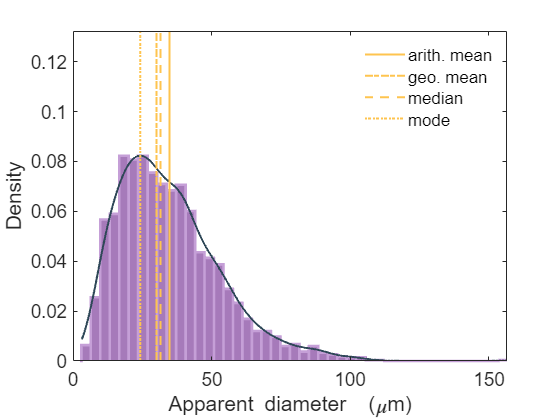

% Plot the distribution of grain diameters
plot_distr(ecds);

Everything is similar except the density values...TODO

 
DESCRIPTIVE STATISTICS from plot_wtdArea
Area-weighted mean = 53.8826 um
---------------------------------------
HISTOGRAM FEATURES from plot_wtdArea
Modal interval = 50 - 55 um
Number of classes = 32
As per the auto rule, the bin size = 5


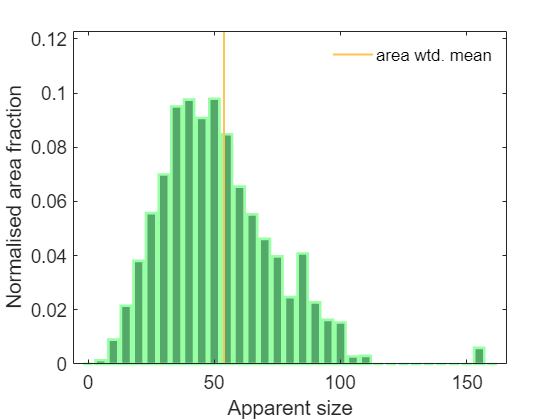

% Plot an area-weighted histogram of a grain diameters
plot_wtdArea(data.("EDCs"), data.("Area"));

**Bin size and thus number of classes are different ! To follow up.**

 
DESCRIPTIONS from plot_qq
Shapiro-Wilk test for lognormality
Data is not lognormally distributed.
Lognormality test: 0.99, 0.04 (test statistic, p-value)


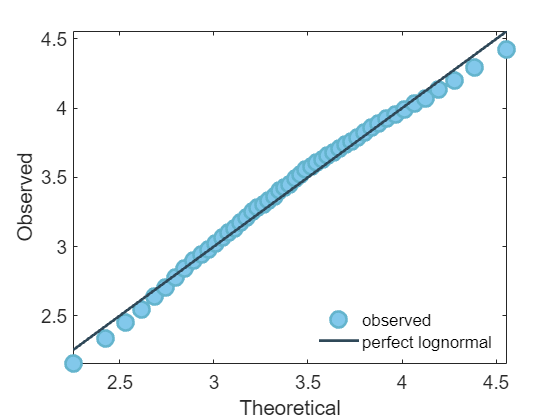

% Plot the lognormal distribution test using a quantile–quantile (q-q) 
% plot and a Shapiro-Wilk test
plot_qq(data.("EDCs"));

 
DESCRIPTIVE STATISTICS from plot_normDistr
Normalized SD = 0.165
KDE bandwidth = 0.036056


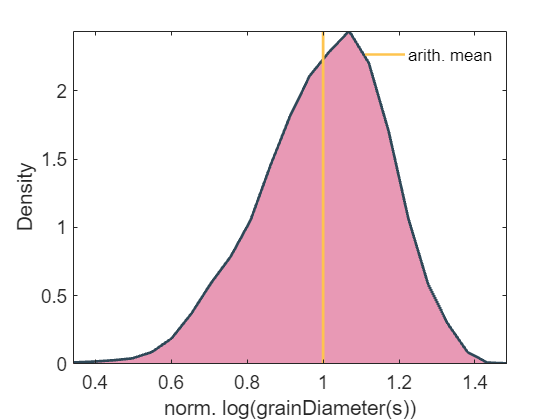

% Plot the log-transformed normalised distribution  of grain diameters
plot_normDistr(data.("EDCs"), data.("Area"));

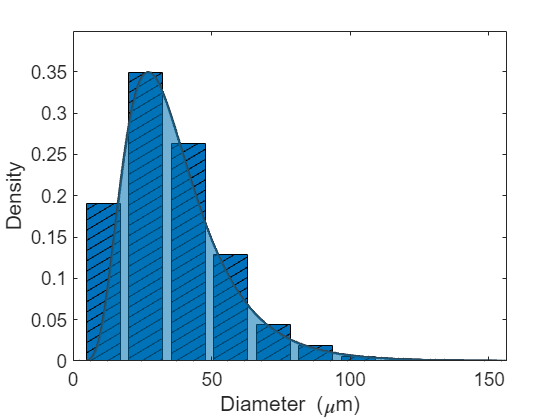

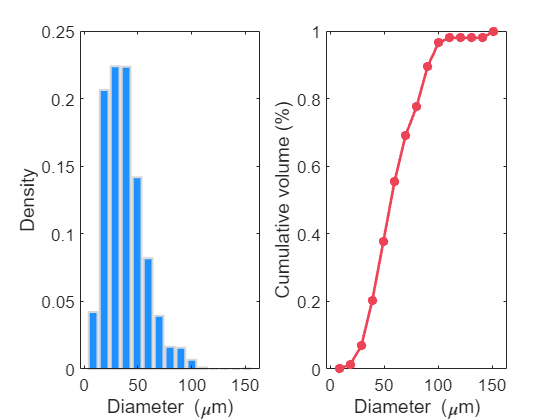

% Find the best parameters for performing the Saltykov method by 
% minimising the Cramer-von Mises (CvM) goodness-of-fit criterion.
out = autoSaltykov(data.("EDCs"));

% plot Saltykov
plot_saltykov(data.("EDCs"), out);

I miss here a report on the calculated optimal values. For example, the number of classes, Lognormal shape and scale (i.e. MSD and geo. mean).

out

out = struct with fields:
     appCounts: [507 930 700 342 116 50 14 1 0 1]
    appCenters: [10.8618 26.2022 41.5426 56.8831 72.2235 87.5639 102.9044 118.2448 133.5852 148.9257]
       appFreq: [0.1905 0.3495 0.2631 0.1285 0.0436 0.0188 0.0053 3.7580e-04 0 3.7580e-04]
        method: 'upper'
          bins: 10
       centers: [8.3050 18.5320 28.7589 38.9859 49.2128 59.4398 69.6668 79.8937 90.1207 100.3476 110.5746 120.8015 131.0285 141.2555 151.4824]
         edges: [3.1915 13.4185 23.6455 33.8724 44.0994 54.3263 64.5533 74.7802 85.0072 95.2342 105.4611 115.6881 125.9150 136.1420 146.3689 156.5959]
          freq: [0.0422 0.2064 0.2240 0.2235 0.1418 0.0819 0.0394 0.0164 0.0158 0.0069 0.0010 0 0 0 5.6793e-04]
           CvM: 3.0953


help plot_saltykov

  Function description:
  Plots two figures:
  Figure 1: % the data histogram based on Saltykov's optimal number of bins
  and best-fit lognormal distribution (two-step method)
 
  Figure 2: Two sub-plots after applying the Saltykov method of: 
  (2.1) a bar plot of Saltykov frequency versus grain size, and
  (2.2) a line plot of Saltykov volume-weighted cumulative frequency.
 
  Author:
  Dr. Azdiar Gazder, 2023, azdiaratuowdotedudotau
 
  Acknowledgements:
  Dr. Marco A. Lopez-Sanchez
  For the original Python script at:
  https://github.com/marcoalopez/GrainSizeTools/blob/master/grain_size_tools/plot.py
 
  https://au.mathworks.com/matlabcentral/answers/1852048-how-to-fit-lognormal-distribution-on-my-data
 
  Syntax:
  plot_saltykov(data

## Checking with a toy dataset

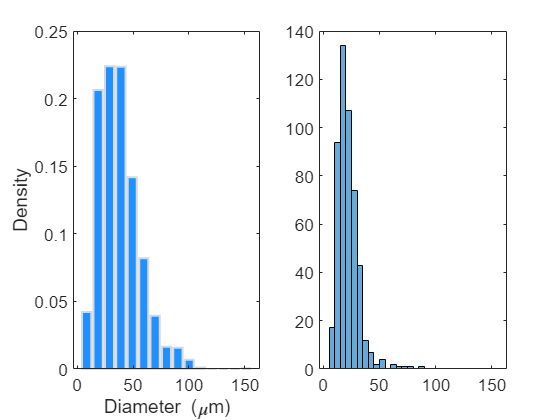

scale = log(20);     % set sample geometric mean to 20
shape = log(1.5);    % set the lognormal shape to 1.5
n = 500;             % sample size = 500

% generate lognormal distribution
toy_data = exp(scale + shape.*randn(n, 1));

histogram(toy_data)

grainStatistics(toy_data)

 
CENTRAL TENDENCY ESTIMATORS
Arithmetic mean = 3.00 um
Confidence intervals at 95.0 %
mCox method: 21.07 - 22.67 (--601.4%, +654.7%), length = 1.599
---------------------------------------
Geometric mean = 20.17 um
Confidence interval at 95.0 %
ASTM (CLT) method: 19.48 - 20.90 (-3.5%, +3.6%), length = 1.420
---------------------------------------
Median = 20.41 microns
Confidence interval at 95.0 %
Robust method: 19.15 - 21.21 (-6.1%, +3.9%), length = 2.053
---------------------------------------
Mode (KDE-based) = 17.43 um
Maximum precision set to 0.05
KDE bandwidth = 2.9766 (Silverman rule-of-thumb)
 
DISTRIBUTION FEATURES
Sample size (n) = 500
Standard deviation = 9.73 (1-sigma)
Lognormal shape (multiplicative standard deviation) = 1.49
Interquartile range (IQR) = 10.84
---------------------------------------
Shapiro-Wilk te

mean(toy_data)

ans = 21.9095

**Something is wrong with the arithmetic mean calculation ! CHECK IT!**

 
DESCRIPTIVE STATISTICS from plot_distr
Number of classes = 19
Bin size = 4.1732
KDE bandwidth = 2.9766


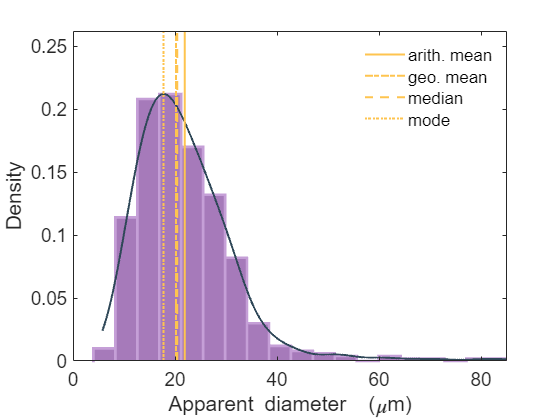

% Plot the distribution of grain diameters
plot_distr(toy_data)